Exercise 1c.

Does this match the predicted anwser from a?  hell yeah it does

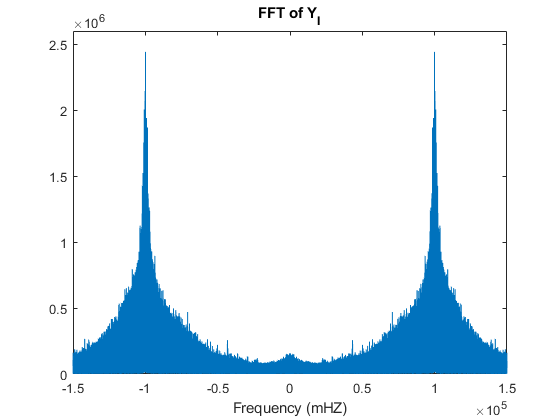

load('data_exercise1c.mat');
figure;
plot_FT(y_I,fs);
xlabel('Frequency (mHZ)');
ylim([0,2.6*10^6])
title('FFT of Y_I');
hold off;

Exercise 1d.

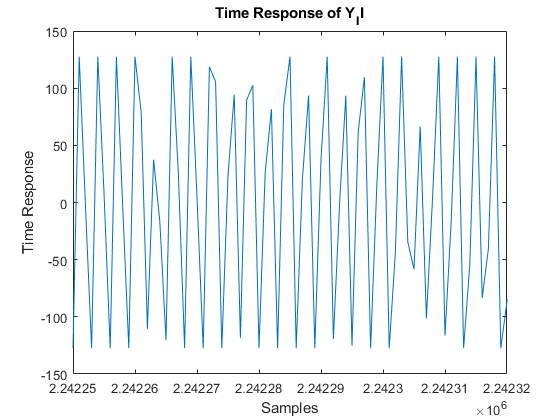

clf;
figure;
plot(y_I)
xlabel('Samples');
xlim([2.24225*10^6,2.24232*10^6])
ylabel('Time Response');
title('Time Response of Y_II');

Exercise 1e.

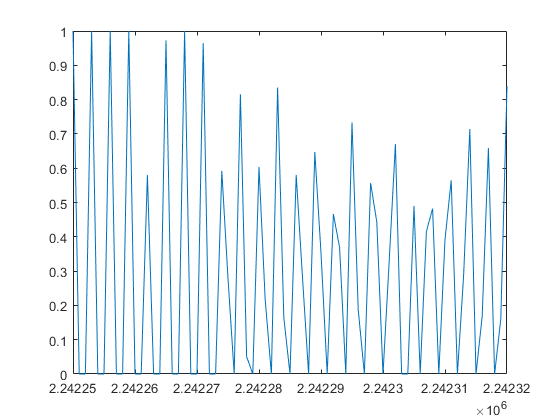

deriv = diff(y_I);
deriv(deriv<0) = 0;
deriv = deriv./max(deriv);
plot(deriv)
xlim([2.24225*10^6,2.24232*10^6])

Exercise 1f.

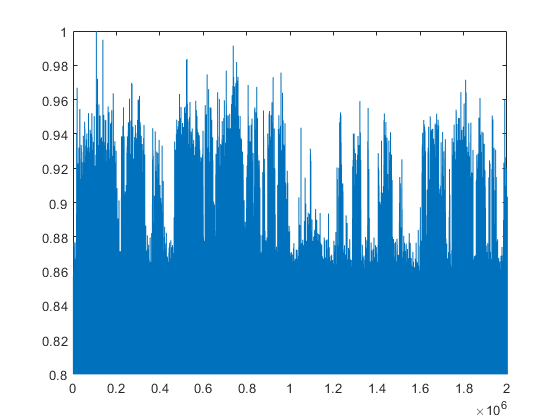

y = lowpass(deriv, 1.5^5, fs);
y = y./max(y);
plot(y);
xlim([0, 2*10^6]);
ylim([.8, 1]);

Exercise 1g.

y = y - mean(y);
y = (y./max(y)).*.1;
y = decimate(y, 4);
sound(y, 300000/4);
audiowrite('audio_out_ex1.mp4',y,fs/4)

Error using audiowrite (line 203)
Unsupported SampleRate value.

Exercise 2b.

load('45gain.mat')

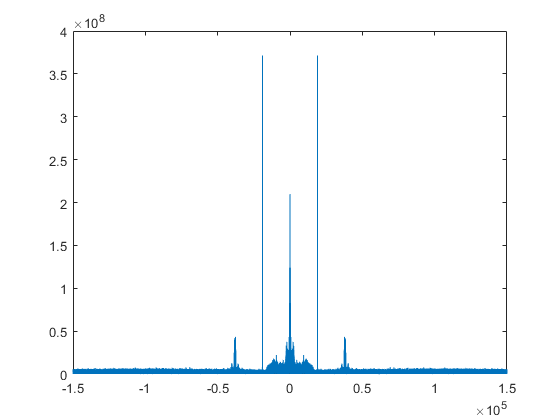

y_Ip = y_I_2;
y_Qp = y_Q_2;
a = diff(y_Qp);
m = (diff(y_Qp).*y_Ip(1:length(y_Ip)-1)) - (diff(y_Ip).*y_Qp(1:length(y_Qp)-1));
figure;
plot_FT(m,fs_2);

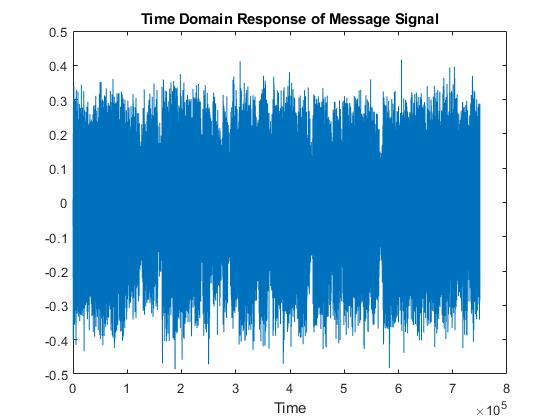


m = lowpass(m, 1.5^5, fs_2);
m = (m/max(abs(m)))*.5;
m = decimate(m,4);
m = m-mean(m);
figure;
plot(m);
title('Time Domain Response of Message Signal')
xlabel('Time')

%sound(m,fs_2/4);
audiowrite('audio_out_ex2.mp4',m,fs_2)

Error using audiowrite (line 203)
Unsupported SampleRate value.